## **TRAINING SESSION**

How to simulate and automate the design of a THz metasurface reflector.

`Author: David Moreno Gallego de la Sacristana `

`Email: david.moreno.gs@gmail.com`

##  1. INTRODUCTION  

Within this notebook, we outline the step-by-step process for simulating a unit cell. Additionally, we cover the final stage of the simulation, constructing the complete metaline.

*Caution: you need to modify the filepath and filename (Section 2. Simulation) to be able to run this code.*

### 1.1. Creating the project and initializing settings

Initially, we establish an interface for communication with CST by creating a COM automation server, acquiring "cst" as the handle for the server's interface. Following that, we proceed to create the project and define units.

clear all
close all
clc

%% Start CST Studio
cst = actxserver('CSTStudio.application');

% Create new worksheet
global mws;
mws = invoke(cst, 'NewMWS');

% Project settings

% Define units
Geometry = 'um';
Frequency = 'THz';
Time = 'ps';
CstDefineUnits(Geometry, Frequency, Time);

## 2. UNIT CELL DESIGN AND OPTIMIZATION  

After defining the project and initializing the main properties, we proceed to create the shape for simulation.

### 2.1. Modeling

First, we store the variables in CST. Following that, we start shaping the forms. To complete the shape modeling, we extrude a face to subtract it from the ring shape, resulting in the formation of the C-shape, allowing us to customize the angle of aperture.

% -------------------------------
% --------- Variables -----------
% -------------------------------
ts=156; % Substrate thickness
tm=10; % Metal thickness
r=233; % Ring outer radius
w=40; % Ring width
a=22.5; % Angle
l=680; % Lattice

mws.invoke('StoreParameter',"ts", string(ts)); % Substrate thickness
mws.invoke('StoreParameter',"tm",string(tm)); % Metal thickness
mws.invoke('StoreParameter',"r",string(r)); % Ring outer radius
mws.invoke('StoreParameter',"w",string(w)); % Ring width
mws.invoke('StoreParameter',"a",string(a)); % Lattice
mws.invoke('StoreParameter',"l",string(l)); % Lattice

mws.invoke('Rebuild'); %rebuild a structure
mws.invoke('Mesh','Update');

% Define new material
nameMat2 = 'Paper';
eps = 1.5^2;
mu = 1;
tand = 0;
col = [0.6, 0.2, 0];
trans = 90;
DefineMaterial(nameMat2,eps,mu,tand,col,trans)

% -------------------------------
% ---------- Modeling -----------
% -------------------------------

%Create Substrate box
nameS = ['Box1'];
componentS = ['Substrate'];
x = [-l/2, l/2];
y = [-l/2, l/2];
z = [0, ts];
material = nameMat2;
CreateBrick(nameS,componentS,x,y,z,material)

% Create meta-atom ring
nameM = ['Cyl1'];
componentM = ['Metaatom'];
ro = r;
ri = r-w;
axis = ['z'];
h=[string(tm)];
xc=0;
yc=0;
zrange=[ts,ts+tm];
materialM = 'PEC';
CreateCylinder(nameM,componentM,ro,ri,axis,zrange,xc,yc,materialM);

% Create shape
nameM1 = 'Substract1';
componentM = 'Metaatom';
x = [-r/100, r/100];
y = [-r/100, r/100];
z = [ts, ts+tm];
materialM1 = 'Vacuum';
CreateBrick(nameM1,componentM,x,y,z,materialM1)

% Extrude shape
mws.invoke('AddToHistory', ['pick face'],['Pick.PickFaceFromId "' componentM ':' nameM1 '","6"']);

mode='Picks';
height=r;
taper=a;
twist=0;
nameM2='substract2';
ExtrudeShape(nameM1,nameM2,componentM,materialM1, mode, height, twist, taper);

% Substract shape
SubtractShape(componentM, nameM, componentM, nameM2);

mws.invoke('Rebuild'); %rebuild a structure
mws.invoke('Mesh','Update');

### 2.2. Simulation

`[TO MODIFY] We need to define the filename and filepath:`

try
    filepath = 'C:\Users\dmorgal\Documents\CST\';
    filename = 'TERAOPTICS_training';
    iteration='1';
catch
    warning('Problem  during name creation');
end

We define the frequency solver, boundaries and Floquet port modes. Once the solver is executed, we proceed to postprocess the results and store them.

% Frequency range
Solver = invoke(mws,'Solver');
invoke(Solver,'FrequencyRange',"0.05","0.35");

% Change solver type
change2FSolver;
FDSolver = invoke(mws,'FDSolver');
invoke(FDSolver,'Reset');
invoke(FDSolver,'SetMethod',"Tetrahedral","General purpose");
invoke(FDSolver,'MeshAdaptionTet','True');
invoke(FDSolver,'Stimulation',"Zmin","All");

%Boundaries
Boundary = invoke(mws,'Boundary');
invoke(Boundary,'Xmin', "unit cell");
invoke(Boundary,'Xmax', "unit cell");
invoke(Boundary,'Ymin', "unit cell");
invoke(Boundary,'Ymax', "unit cell");

FloquetPort = mws.invoke('FloquetPort');
invoke(FloquetPort,'Port', 'Zmax');
invoke(FloquetPort,'SetNumberOfModesConsidered', '2');

invoke(FloquetPort,'Port', 'Zmin');
invoke(FloquetPort,'SetNumberOfModesConsidered', '2');

%-------- Save -----------------
mws.invoke('SaveAs',[filepath, filename, iteration,'.cst'],'True');


invoke(FDSolver,'Start');

exportpath=[filepath, filename, iteration,'\Export\s21'];

mws.invoke('SelectTreeItem', "1D Results\S-Parameters\SZmax(2),Zmin(2)"); % Change with the name
plot1d=mws.invoke('Plot1D');
plot1d.invoke('PlotView','real');
ASCIIExport = invoke(mws,'ASCIIExport');
invoke(ASCIIExport,'Reset');
invoke(ASCIIExport,'Filename',[exportpath '_re.txt']);

try
    invoke(ASCIIExport,'Execute');
catch
    warning('Problem during the simulation');
end

plot1d.invoke('PlotView','imaginary');
ASCIIExport = invoke(mws,'ASCIIExport');
invoke(ASCIIExport,'Reset');
invoke(ASCIIExport,'Filename',[exportpath '_im.txt']); % Can be hdf5

try
    invoke(ASCIIExport,'Execute');
catch
    warning('Problem during the simulation');
end


### 2.3. Processing results

We generate the plots in Matlab by reading the previously stored ASCII files.

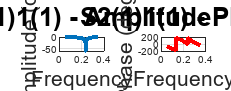

s21_re = readmatrix([exportpath '_re.txt']);
freq=s21_re(:,1);
s21_im = readmatrix([exportpath '_im.txt']);

% Plot Amplitude
figure('units','normalized','outerposition',[0 0.2 1 0.7]);
subplot(1,2,1)
set(gcf,'color','w');
plot(freq, 10*log10(abs(s21_re(:,2)).^2+abs(s21_im(:,2)).^2),"LineWidth",3);
xlabel("Frequency", 'FontSize', 16);
ylabel("Amplitude (dB)", 'FontSize', 16);
title("S2(1)1(1) - Amplitude", 'FontSize', 20);
grid on;

hold on;

% Plot phase
subplot(1,2,2)
p1=plot(freq, rad2deg(angle(s21_re(:,2)+1j*s21_im(:,2))),'Color','r',"LineWidth",3);
xlabel("Frequency", 'FontSize', 16);
ylabel("Phase (deg)", 'FontSize', 16);
t=title("S2(1)1(1) - Phase", 'FontSize', 20);
grid on;

The next step would be doing a parameter sweep. For that, you simply include the previous code in a for loop iterating the variables you would like to explore

Then, once we discover our target meta-atoms, we build the metaline in this way.

clear all;

cst = actxserver('CSTStudio.application');
global mws;
mws=invoke(cst, 'NewMWS');

% Project settings
% Define units
Geometry = ['um'];
Frequency = ['THz'];
Time = ['ps'];

DefineUnits(Geometry, Frequency, Time);

% -------------------------------
% --------- Variables -----------
% -------------------------------

ts=156; % Substrate thickness
w=40; % Ring widt
tm=0.001; % Metal thickness
r=[310, 289, 270, 260, 310, 289, 270, 260]; % Ring outer radius
a=[5.5, 23.5, 58.5, 70, 5.5, 23.5, 58.5, 70] ; % Angle
rot=[45,45,45,45,-45,-45,-45,-45];
l=680; % Lattice

% Define new material
nameMat2 = 'Paper';
eps = 1.5^2;
mu = 1;
tand = 0;
col = [0.6, 0.2, 0];
trans = 90;
DefineMaterial(nameMat2,eps,mu,tand,col,trans)

numElements= 8;

for i=1:1:numElements

    mws.invoke('StoreParameter',"ts", num2str(ts)); % Substrate thickness
    mws.invoke('StoreParameter',"tm",num2str(tm)); % Metal thickness
    mws.invoke('StoreParameter',"r",num2str(r(i))); % Ring outer radius
    mws.invoke('StoreParameter',"w",num2str(w)); % Ring width
    mws.invoke('StoreParameter',"a",num2str(a(i))); % Lattice
    mws.invoke('StoreParameter',"l",num2str(l)); % Lattice
    mws.invoke('StoreParameter',"rot",num2str(rot(i))); % Lattice
    
    mws.invoke('Rebuild'); %rebuild a structure
    mws.invoke('Mesh','Update');
    
    % -------------------------------
    % ---------- Modeling -----------
    % -------------------------------
    
    
    %Create Substrate box
    nameS = ['Box1',num2str(i)];
    componentS = ['Substrate'];
    x = [-l/2, l/2];
    y = [-l/2, l/2];
    z = [0, ts];
    material = nameMat2;
    createBrick(nameS,componentS,x,y,z,material)
    
    % Create meta-atom ring
    nameM = ['Cyl1',num2str(i)];
    componentM = ['Metaatom'];
    ro = r(i);
    ri = r(i)-w;
    axis = ['z'];
    h=[num2str(tm)];
    xc=0;
    yc=0;
    zrange=[ts,ts+tm];
    materialM = 'PEC';
    createCylinder(nameM,componentM,ro,ri,axis,zrange,xc,yc,materialM);
    
    % Create shape
    nameM1 = ['substract1',num2str(i)];
    componentM = 'Metaatom';
    x = [-r(i)/10, r(i)/10];
    y = [-r(i)/10, r(i)/10];
    z = [ts, ts+tm];
    materialM1 = 'Vacuum';
    createBrick(nameM1,componentM,x,y,z,materialM1)
    
    %Rotation of the c-shape
    mws.invoke('AddToHistory', ['transform: rotate ', componentM, ':', nameM1],[...
    sprintf('With Transform\n')...
    sprintf('  .Reset \n')...
    sprintf(['  .Name"', componentM,':',nameM1, '" \n'])...
    sprintf('  .Origin "CommonCenter" \n')...
    sprintf(['  .Center "', num2str(l*(i-1)),'", "0", "0"\n'])...
    sprintf(['  .Angle "0", "0", "', num2str(rot(i)),'"\n'])...
    sprintf('  .MultipleObjects "False"\n')...
    sprintf('  .GroupObjects "False"\n')...
    sprintf('  .Repetitions "1"\n')...
    sprintf('  .MultipleSelection "False"\n')...
    sprintf('  .AutoDestination "True" \n')...
    sprintf('  .Transform "Shape", "Rotate" \n')...
    sprintf('  End With')]);
    
    % Extrude shape
    mws.invoke('AddToHistory', ['pick face'],['Pick.PickFaceFromId "', componentM, ':', nameM1, '","6"']);
    
    mode='Picks';
    height=r(i);
    taper=a(i);
    twist=0;
    nameM2=['substract2',num2str(i)];
    extrudeShape(nameM1,nameM2,componentM,materialM1, mode, height, twist, taper);
    
    % Substract shape
    subtractShape(componentM, nameM, componentM, nameM2);
    
    mws.invoke('Rebuild'); %rebuild a structure
    mws.invoke('Mesh','Update');
    moveLocalCoordinates(l*i,0,0);
end

For simulating this metaline, I suggest referring to the training video, where we follow these steps:

- Definition of time solver.

- Frequency range.

- Boundaries condition (z open, x periodic, y periodic).

- Background open space addition in z axis.

- Plane wave excitation with x polarization and z propagation.

- Field monitor detection in 0.2THz.

- Run solver with hexahedral mesh.

In the post-processing step, we will observe the deflection by visualizing the field on the plane of polarization and propagation.

`Copyright (C) David Moreno Gallego de la Sacristana, 2023`

`david.moreno.gs@gmail.com`

`Permission is hereby granted, free of charge, to any person obtaining a copy of this software and associated documentation files (the "Software"), to use the Software for non-commercial purposes only. Any distribution of the Software or modifications thereof is strictly prohibited without written consent from the author.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY, FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE SOFTWARE.`

`For commercial use or distribution, please contact the author.`